# 案例：最小二乘法数据拟合

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

### 线性拟合

    模型：$y=k*x+b$；

    已知一系列 $x$ 和 $y$，求解未知参数 $a$ 和 $b$；

    求解方法：polyfit、左除；

### 多项式拟合

    模型：$y = p_1*x^{n}+p_2*x^{n-1}+\cdots+p_{n+1}$；

    已知一系列 $x$ 和 $y$，求解未知参数$p_1、p_2、\cdots、p_{n+1}$；

    求解方法：polyfit、左除；

### 多元线性拟合

    模型：$y=k1*x1+k2*x2+b$；

    求解方法：regress、左除；

### 多元多项式拟合

    模型：$f(x,y)=a_{20}*x^2+a_{02}*y^2+a_{11}*xy+a_{10}*x+a_{01}*y+a_{00}$；

    求解方法：lsqcurvefit、nlinfit、regress、左除；

### 非线性拟合

    求解方法：lsqcurvefit、nlinfit、高斯牛顿法、Levenberg-Marquardt；

以指数拟合为例：

模型：$f(A,B,C,x)=A*epx(-\frac{x}{B})+C $

残差：$r = f(A,B,C,x) - (A*epx(-\frac{x}{B})+C) $

目标函数：$F(A,B,C,x) = min{||f(A,B,C,x) - (A*epx(-\frac{x}{B})+C)||^2} = r'*r$

模型函数分别对A、B、C求偏导数得到 Jacobi 矩阵：

    
$$J_A = \frac{\partial f}{\partial A} = exp(-\frac{x}{B})   \\
J_B = \frac{\partial f}{\partial B} = A*x*exp(-\frac{x}{B})/B^2   \\
J_C = \frac{\partial f}{\partial C} = ones(len, 1)$$


目标函数对A、B、C求偏导数得到梯度矩阵：

    
$$g_A = \frac{\partial F}{\partial A} = -2*J_A*r   \\
g_B = \frac{\partial F}{\partial B} = -2*J_B*r   \\
g_C = \frac{\partial F}{\partial C} = --*J_C*r  \\
g = -2*J'*r$$


计算目标函数的 Hessian 矩阵：

    
$$\left[
\begin{array}{l}
\frac{\partial ^2F}{\partial ^2A}    \  \      \frac{\partial F\partial F}{\partial A \partial B}     \  \      \frac{\partial F\partial F}{\partial A \partial C}  \\
\frac{\partial F\partial F}{\partial A \partial B}    \  \      \frac{\partial ^2F}{\partial ^2B}     \  \     \frac{\partial F\partial F}{\partial B \partial C}   \\
 \frac{\partial F\partial F}{\partial A \partial C}    \  \      \frac{\partial F\partial F}{\partial B \partial C}    \  \      \frac{\partial ^2F}{\partial ^2C}   \\            
\end{array}
\right]
=-2*J'*J$$


高斯牛顿法计算更新步长：$x=-H  \backslash  g$

Levenberg-Marquardt 更新步长和正则化参数：

    
$$x=-H  \backslash  g   \\
x = -(H+\lambda*I)\backslash  g  \\
if F_new >F  \\
\ \  \hat x = \hat x + x   \\
\ \   \lambda = 0.1 * \lambda  \\
else \\
\ \    \lambda = 10 * \lambda$$


**障碍罚函数约束**，构造一个辅助函数来求解最优化问题，假设约束条件为 A、B、C 大于等于 0：

    
$$G(x, \mu) = f(x) + \mu*B(x)  = f(x) + \mu*\sum^n_{i=1}ln[g_i(x)] = f(x) -\mu*(ln(A) + ln(B) + ln(C))$$


原目标函数变为：$F(x) = r'*r-\mu*(ln(A) + ln(B) + ln(C))$

迭代步长：

    
$$g = -2*J'*r - \mu*[\frac{1}{A}, \frac{1}{B}, \frac{1}{C}]  \\
H = 2*J'*J - \mu*diag([-\frac{1}{A^2}, -\frac{1}{B^2}, -\frac{1}{C^2}])   \\
x = -(H+\lambda*I) \backslash  g$$


**无约束最优化**，求解问题变换形式，然后按照正常方式求解：

    
$$M(t) = a^2*exp(-\frac{x}{b^2}) + c^2  \\
A = a^2, \ \ B = b^2, \ \  C = c^2$$


clear;clc;close all;
%%%%%%%%%%%%%%%%%%%% 线性拟合 %%%%%%%%%%%%%%%%%%%%
% 保证结果可重复
rng('default');
% 生成数据
len = 20;
x = linspace(0, 10, len);
y = 2*x + 2;
% 添加噪声
y_noise = y + randn(1, len);
% 调用 polyfit 函数
p = polyfit(x, y_noise, 1)

p =     2.0916    2.2068


% 拟合结果
y_fit = polyval(p, x);
% 左除
pp = [x', ones(len, 1)] \ y_noise'

pp =     2.0916
    2.2068


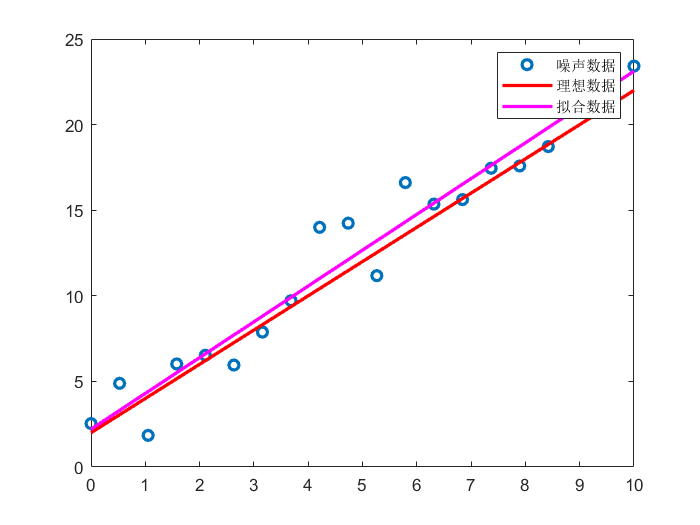

% 显示结果
figure;
plot(x, y_noise, 'o', 'LineWidth', 2);
hold on
plot(x, y, 'r', 'LineWidth', 2);
plot(x, y_fit, 'm', 'LineWidth', 2);
hold off
legend('噪声数据', '理想数据', '拟合数据');

%%%%%%%%%%%%%%%%%%%% 多项式拟合 %%%%%%%%%%%%%%%%%%%%
% 保证结果可重复
rng('default');
% 生成数据
len = 40;
x = linspace(-10, 10, len);
y = 2*x.^2 + 2*x + 2;
% 添加噪声
y_noise = y + 5*randn(1, len);
% 调用 polyfit 函数
p = polyfit(x, y_noise, 2)

p =     1.9509    1.7185    5.2369


% 拟合结果
y_fit = polyval(p, x);
% 左除
pp = [x.^2', x', ones(len, 1)] \ y_noise'

pp =     1.9509
    1.7185
    5.2369


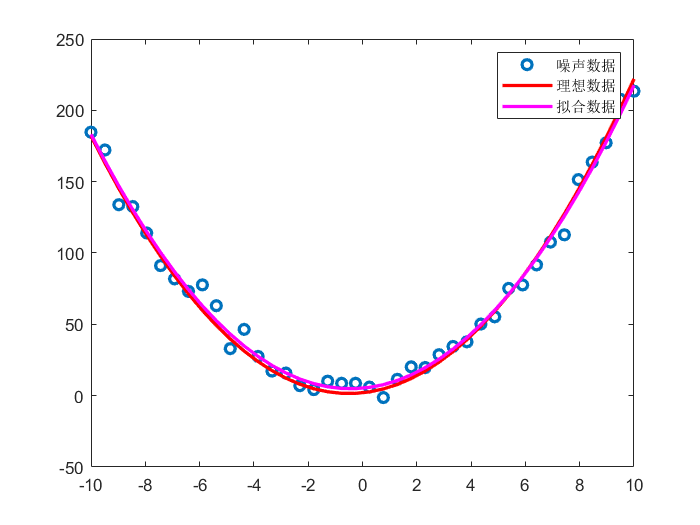

% 显示结果
figure;
plot(x, y_noise, 'o', 'LineWidth', 2);
hold on
plot(x, y, 'r', 'LineWidth', 2);
plot(x, y_fit, 'm', 'LineWidth', 2);
hold off
legend('噪声数据', '理想数据', '拟合数据');

%%%%%%%%%%%%%%%%%%%% 多元线性拟合 %%%%%%%%%%%%%%%%%%%%
% 保证结果可重复
rng('default');
% 生成数据
len = 50;
x = randi(50, len, 1);
y = randi(50, len, 1);
f = 5*x + 10*y + 2;
% 添加噪声
f_noise = f + 5*randn(len, 1);
% 调用 regress 函数
X = [x, y, ones(len, 1)];
p = regress(f_noise, X)

p =     4.9515
    9.9540
    3.4947


% 拟合结果
f_fit = p(1)*x + p(2)*y + p(3);
% 左除
pp = X \ f_noise

pp =     4.9515
    9.9540
    3.4947


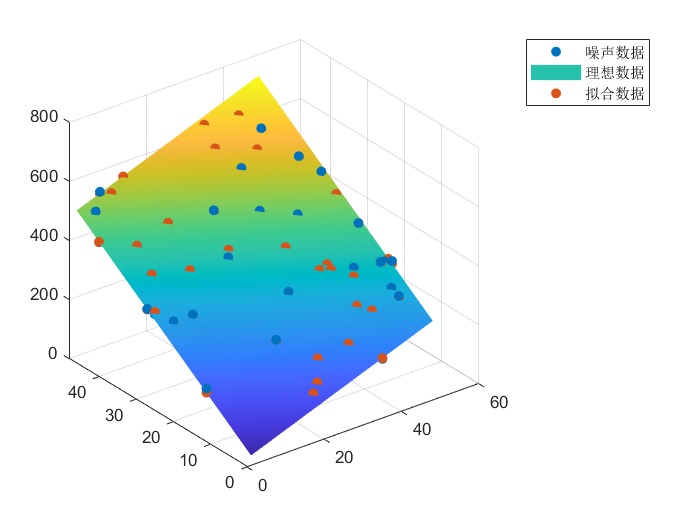

% 显示结果
figure;
scatter3(x, y, f_noise, 'filled');
hold on
[xx, yy] = meshgrid(x, y);
surf(xx, yy, 5*xx + 10*yy + 2);
shading interp
scatter3(x, y, f_fit, 'filled');
hold off
legend('噪声数据', '理想数据', '拟合数据');

%%%%%%%%%%%%%%%%%%%% 多元多项式拟合 %%%%%%%%%%%%%%%%%%%%
% 保证结果可重复
rng('default');
% 生成数据
len = 50;
x = randi(50, len, 1) / 5;
y = randi(50, len, 1) / 5;
fun = @(p, x, y) p(1)*x.^2 + p(2)*y.^2 + p(3)*x.*y + p(4)*x + p(5)*y + p(6);
p0 = [5, 10, 5, 10, 10, 2];
f = fun(p0, x, y);
% 添加噪声
f_noise = f + 10*randn(len, 1);
[xx, yy] = meshgrid(x, y);
ff = fun(p0, xx, yy);
% 调用 lsqcurvefit
func = @(var, x) var(1)*x(:,1).^2 + var(2)*x(:,2).^2 + var(3)*x(:,1).*x(:,2) + var(4)*x(:,1) + var(5)*x(:,2) + var(6);
p = lsqcurvefit(func, ones(1, 6), [x, y], f_noise)


Local minimum possible.
lsqcurvefit stopped because the size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


p =     5.5886   10.1702    5.3043    1.8132    6.0309   28.3331


% 拟合结果
f_fit = func(p, [x, y]);
% 调用 nlinfit
pp = nlinfit([x, y], f_noise, func, ones(1, 6))

pp =     5.5886   10.1702    5.3043    1.8132    6.0309   28.3330


% 调用 regress
X = [x.^2, y.^2, x.*y, x, y, ones(len, 1)];
ppp = regress(f_noise, X)

ppp =     5.5886
   10.1702
    5.3043
    1.8132
    6.0309
   28.3330


% 左除
pppp = X \ f_noise

pppp =     5.5886
   10.1702
    5.3043
    1.8132
    6.0309
   28.3330


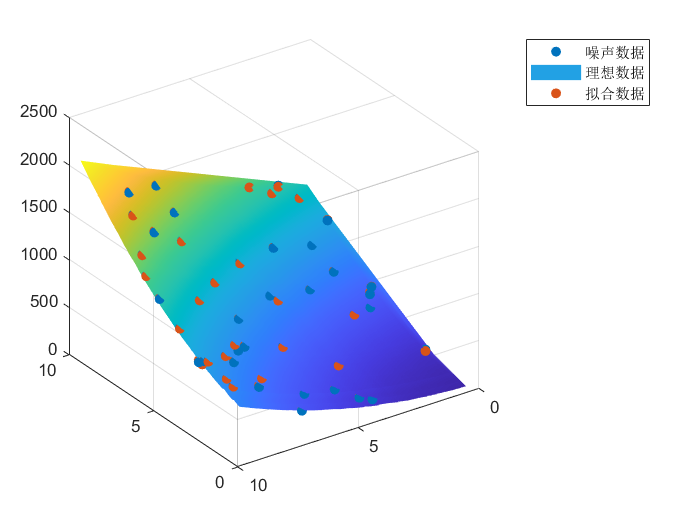

% 显示结果
figure;
scatter3(x, y, f_noise, 'filled');
hold on
[xx, yy] = meshgrid(x, y);
surf(xx, yy, fun(p, xx, yy));
shading interp
view([-145 -30]);
scatter3(x, y, f_fit, 'filled');
hold off
legend('噪声数据', '理想数据', '拟合数据');

%%%%%%%%%%%%%%%%%%%% 非线性拟合 %%%%%%%%%%%%%%%%%%%%
% 保证结果可重复
rng('default');
% 生成数据
len = 1000;
x = linspace(0.1, 300, len)';
y = 300*exp(-x/5) + 10;
% 添加噪声
y_noise = y + 20*randn(len, 1);
% 调用 lsqcurvefit
func = @(p, x) p(1)*exp(-x/p(2)) + p(3);
% 选择合适的初始值
p0 = [100, 2 1];
p = lsqcurvefit(func, p0, x, y_noise)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


p =   312.3520    5.2050    8.9263


% 拟合结果
y_fit_lsq = func(p, x);
% 调用 nlinfit
pp = nlinfit(x, y_noise, func, p0)

pp =   312.3502    5.2051    8.9262


y_fit_nlin = func(pp, x);
% Levenberg-Marquardt 求解
p1 = LSFittingExpFree(x, y_noise)

反演收敛，迭代次数：8


p1 =   312.3503    5.2051    8.9262


p2 = LSFittingExpPenalty(x, y_noise)

反演收敛，迭代次数：23
反演收敛，迭代次数：17
反演收敛，迭代次数：24
反演收敛，迭代次数：17
反演收敛，迭代次数：24


p2 =   312.3503    5.2051    8.9262


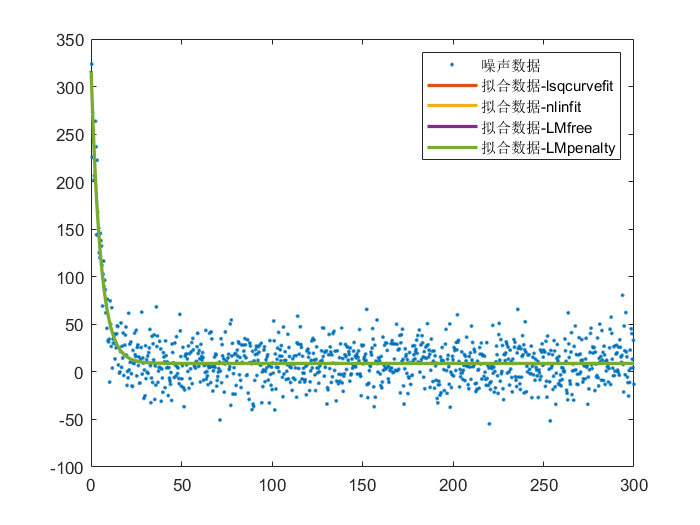

fit1 = func(p1, x);
fit2 = func(p2, x);
% 显示结果
figure;
plot(x, y_noise, '.', 'LineWidth', 2);
hold on
plot(x, y_fit_lsq, 'LineWidth', 2);
plot(x, y_fit_nlin, 'LineWidth', 2);
plot(x, fit1, 'LineWidth', 2);
plot(x, fit2, 'LineWidth', 2);
hold off
legend('噪声数据', '拟合数据-lsqcurvefit', '拟合数据-nlinfit', '拟合数据-LMfree', '拟合数据-LMpenalty');

function result = LSFittingExpFree(x, y)
% Levenberg_Marquardt LS Fitting
% 按列排
x = x(:);
y = y(:);
% 归一化
maxValue = max(y);
y = y / maxValue;
M = length(x);
% Least Squares Minimization 
rng('default');
% 初始值
a = sqrt(rand);
b = sqrt(rand);
c = sqrt(rand);
% 变量个数
nParam = 3;
% 残差
r = y - (a^2 * exp(-x / b^2) + c^2);
% 目标函数
f = r'*r;   
% 正则化因子初值
lambda = 1;     
% 迭代次数
it = 0;         
% 更新标记
updateFlag = true;                  
 % 最大迭代次数
maxIter = 100;    
% 迭代计算
while it < maxIter
    it = it + 1;
    if updateFlag
        Ja = 2 * a * exp(-x / b^2);
        Jb = 2 * a^2 * x .* exp(-x / b^2) / b^3;
        Jc = 2 * c * ones(M, 1);
        J = [Ja, Jb, Jc];
        g = -2 * J' * r;
        H = 2 * (J'*J);
    end
    Hess = H + lambda * eye(nParam);
    s = -Hess \ g;
    a1 = a + s(1);
    b1 = b + s(2);
    c1 = c + s(3);
    r1 = y - (a1^2 * exp(-x / b1^2) + c1^2);
    f1 = r1'*r1;
    fdr = (f - f1) / f;
    if fdr > 0
        a = a1;
        b = b1;
        c = c1;
        f = f1;
        r = r1;
        lambda = 0.1 * lambda;
        updateFlag = true;
    else
        lambda = 10 * lambda;
        updateFlag = false;
    end
    if max(abs(s)) < 1e-6
        disp(['反演收敛，迭代次数：' num2str(it)]);
        break;
   elseif it == maxIter
        disp('反演可能不收敛；');
    end
end
result = [a^2 * maxValue, b^2, c^2 * maxValue];
end

function result = LSFittingExpPenalty(x, y)
% Levenberg_Marquardt LS Fitting
% 按列排
x = x(:);
y = y(:);
M = length(x);
% 初始值
a0 = rand;
b0 = rand;
c0 = rand;
% 变量个数
nParam = 3;
% 残差
r0 = y - (a0 * exp(-x / b0) + c0);
% 障碍罚函数的收缩系数个数
numLoop = 5;
% 最大迭代次数
maxIter = 100;
% 障碍罚函数收缩系数
mu = 10;
k = 0;
while k < numLoop
    k = k + 1;
    mu = mu * 0.1;
    % Least Squares Minimization
    a = a0;
    b = b0;
    c = c0;
    r = r0;
    % 目标函数值
    f = r'*r - mu * (log(a) + log(b) + log(c));
    % 正则化因子初值
    lambda = 1;
    % 迭代次数
    it = 0;
    % 更新标记
    updateFlag = true;
    % 迭代计算
    while it < maxIter
        it = it + 1;
        if updateFlag
            Ja = exp(-x / b);
            Jb = a * x .* exp(-x / b) / b^2;
            J = [Ja, Jb, ones(M, 1)];
            g = -2 * J' * r - mu * [1/a; 1/b; 1/c];
            H = 2 * (J'*J) - mu * diag([-1/a^2, -1/b^2, -1/c^2]);
        end
        s = -(H + lambda * eye(nParam)) \ g;
        while a + s(1) < 0 || b + s(2) < 0 || c + s(3) < 0
            s = 0.5 * s;
        end
        a1 = a + s(1);
        b1 = b + s(2);
        c1 = c + s(3);
        r1 = y - (a1 * exp(-x / b1) + c1);
        f1 = (r1'*r1) - mu * (log(a1) + log(b1) + log(c1));
        fdr = (f - f1) / f;
        if fdr > 0
            a = a1;
            b = b1;
            c = c1;
            f = f1;
            r = r1;
            lambda = 0.1 * lambda;
            updateFlag = true;
        else
            lambda = 10 * lambda;
            updateFlag = false;
        end
        if max(abs(s)) < 1e-6
            disp(['反演收敛，迭代次数：' num2str(it)]);
            break;
        elseif it == maxIter
            disp('反演可能不收敛；');
        end
    end
    history.a(k) = a;
    history.b(k) = b;
    history.c(k) = c;
    history.ssr(k) = r'*r;
end
[~, minIndex] = min(history.ssr);
a = history.a(minIndex);
b = history.b(minIndex);
c = history.c(minIndex);
result = [a, b, c];
end

